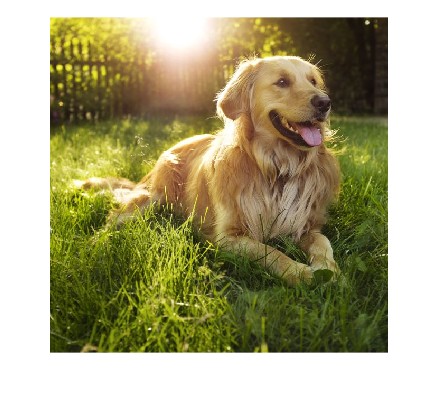

A = imread("img.jpg");
imshow(A)

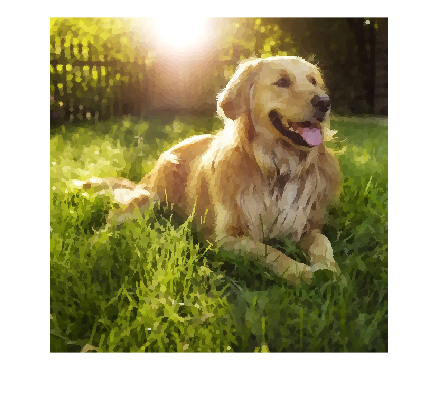



[L,N] = superpixels(A,5000);

outputImage = zeros(size(A),'like',A);
idx = label2idx(L);
numRows = size(A,1);
numCols = size(A,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(A(redIdx));
    outputImage(greenIdx) = mean(A(greenIdx));
    outputImage(blueIdx) = mean(A(blueIdx));
end    

imshow(outputImage)